`Problem1:` *Calculate numerically the radial part of the hydrogen atom wavefunction, using the discretization of the Hamilton operator, as covered in class. You can use the equations from Griffiths, but instead of calculating a polynomial solution analytically, use the one-dimensional solver. You should rewrite the code a bit for using an effective potential instead of the real potential. *

*1) Calculate the radial wavefunctions, plot them together with the analytic solutions, comment on the accuracy of the solution. For the numerical solution, you have to tweak a bit with the Coulomb potential, since it has a singularity to 𝑟 = 0. Calculate the energy levels of the Hydrogen atom!*

A kiadott kódot írtam át a feladat megoldása során, a Coulomb-, és effektív potenciált bevezetve. 

Ábrázolva az analitikus és numerikus megoldást, az energiaszintek nagyon közel esnek, illetve a görbék is nagyon hasonlóak a legalacsonyabb energiaszint(ek)et leszámítva. Az utóbbi görbéje valamiért a negatív tartományba esik, az analitikus megoldással szemben. Külön szekciókban ábrázoltam l=0, 1, 2, 3-ra a legalacsonyabb energiaszintekhez tartozó függvényeket.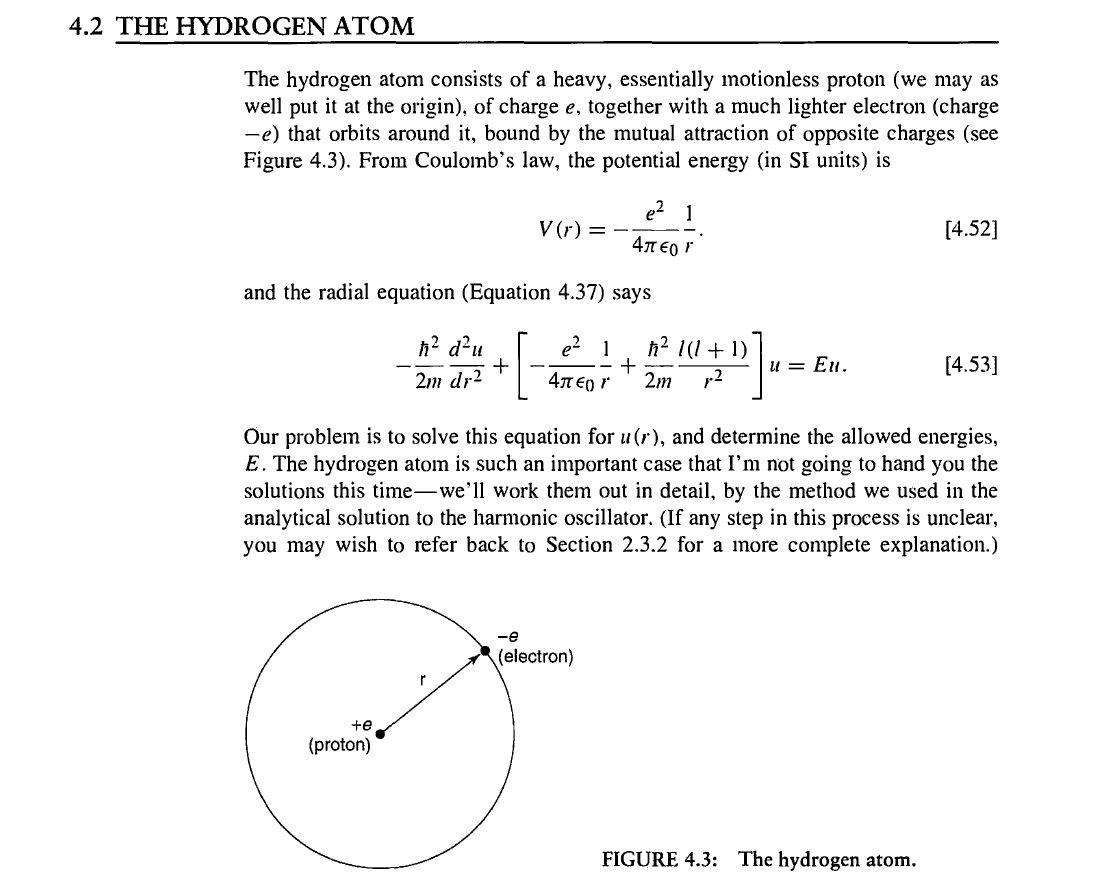

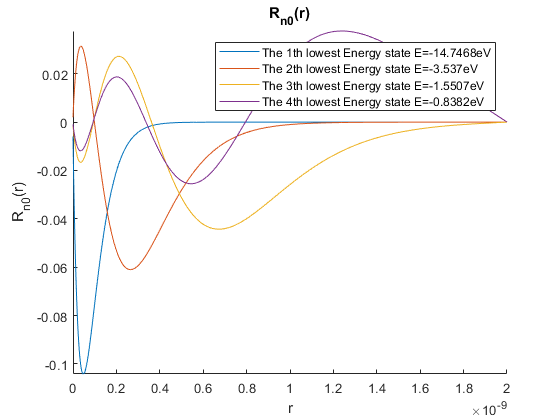

clear variables;
close all;

%Charge of the electron
q_e = 1.602e-19;
%Weight of the electron
m_e = 9.109e-31;
%Planc constant
h = 1.054572e-34;
%The value of h^2/2m
h_ = -h^2/(2.0*m_e);
%Vacuum permittivity
eps0 = 8.854187e-12;
%Length of the observed region
TotalLength = 2e-9;
%Resolution of the observed region
N = 2000;
k_e=1/(4*pi*eps0);

l=0;

Wallenergy = 200*q_e;

%Place the coordinate system

r = linspace(0, TotalLength, N);
dr=TotalLength/N;

V=zeros(1, N);
angular=zeros(1, N);


V=(q_e^2 /(4*pi*eps0))*1./(abs(r));
    
angular=-h_.*((l*(l+1))./(abs(r)).^2);

u=angular-V;
    
H = zeros(N,N);
  for i = 2 : N-1
      H(i,i) = (-2.0*h_/dr^2)+u(i);
      H(i,i-1) = h_/dr^2;
      H(i,i+1) = h_/dr^2;
  end
    

%The sides of the matrix:
%Left side:
H(1,1) = (-2*h_/dr^2)+u(i);
H(1,2) = h_/dr^2;

%Right side:
H(N,N) = (-2*h_/dr^2)+u(i);
H(N,N-1) =h_/dr^2;

[Psi,Emx] = eig(H);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);

for i = 1:N
    E(i) = Emx(i,i);
end

%Finds the first n minimum-energy eigenvalue
n = 4;
E_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:,1) = Psi(:,MinEindex);
E_minValue(1) = MinE;

for i=2:n
    E(MinEindex) = E(MinEindex)+Wallenergy;
    [MinE,MinEindex] = min(E);
    Psi_n(:,i) = Psi(:,MinEindex);
    E_minValue(i) = MinE;
end

figure(1);
title('R_{n0}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat('The',32,num2str(i),'th lowest Energy state E=',num2str(E_minValue(i)/q_e),'eV'));
    xlabel('r')
    ylabel('R_{n0}(r)')
end
legend
axis tight;
hold off;

Analitikus megoldás:

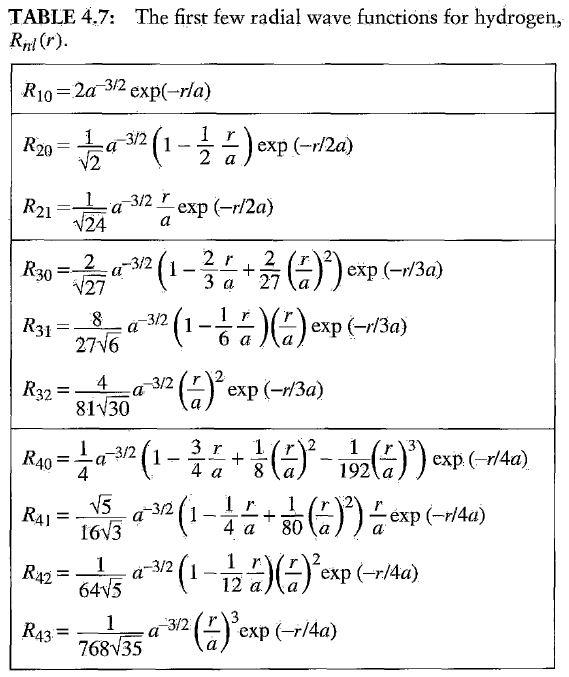

Energiaszintek:

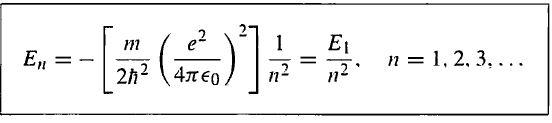

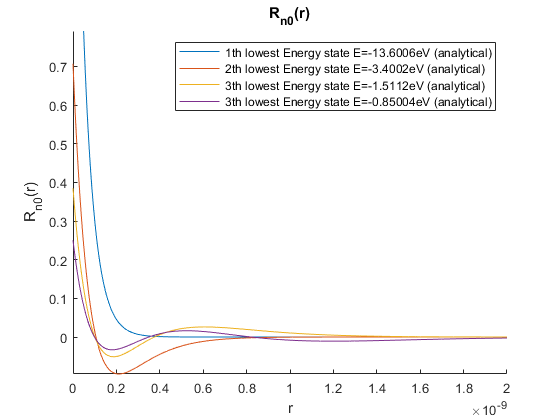

%analytic sol:

a = 5.29e-11;
E10 = -(m_e /(2*h^2)*(k_e*q_e^2)^2);
a_=a^(-3/2);
ar=r./a;

%Rnl; n=1,2,3,4; l=0
R10=2*a_.*exp(-ar);
R20=1/(2^0.5)*a_.*(1-0.5.*ar).*exp(-r./(2*a));
R30=2/(27^0.5)*a_.*(1-2/3*ar + 2/27.*ar.^2).*exp(-r./(3*a));
R40=0.25*a_.*(1-0.75.*ar + 1/8.*ar.^2-1/192.*ar.^3).*exp(-r./(4*a));

figure(2);
title('R_{n0}(r)');
hold on;
plot(r(50:end), a^(3/2).*R10(50:end), 'DisplayName', strcat(32,num2str(1),'th lowest Energy state E=',num2str(E10/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R20, 'DisplayName', strcat(32,num2str(2),'th lowest Energy state E=',num2str(E10*(1/4)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R30, 'DisplayName', strcat(32,num2str(3),'th lowest Energy state E=',num2str(E10*(1/9)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R40, 'DisplayName', strcat(32,num2str(3),'th lowest Energy state E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{n0}(r)')
axis tight;
hold off;

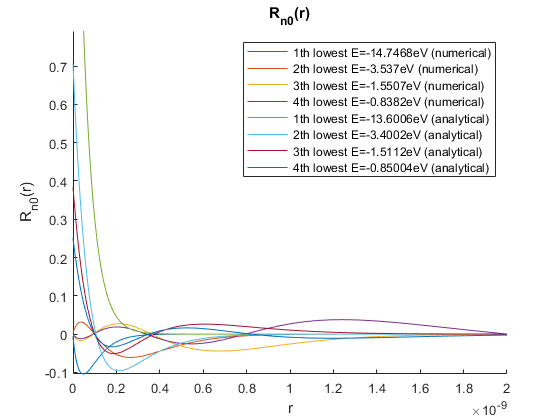


figure(3);
title('R_{n0}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV', ' (numerical)'));
end
plot(r(50:end), a^(3/2).*R10(50:end), 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R20, 'DisplayName', strcat(32,num2str(2),'th lowest E=',num2str(E10*(1/4)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R30, 'DisplayName', strcat(32,num2str(3),'th lowest E=',num2str(E10*(1/9)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R40, 'DisplayName', strcat(32,num2str(4),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{n0}(r)')
axis tight;
hold off;

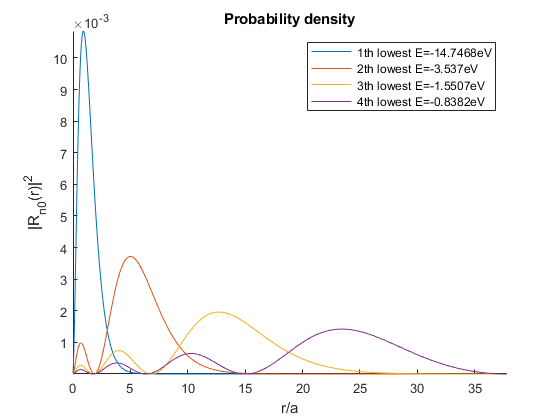


figure(33);
title('Probability density');
for i=1:n
    hold on;
    plot(r./a, abs(Psi_n(:,i)).^2, 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV'));
    xlabel('r/a')
    ylabel('|R_{n0}(r)|^2')
end
legend
axis tight;
hold off;

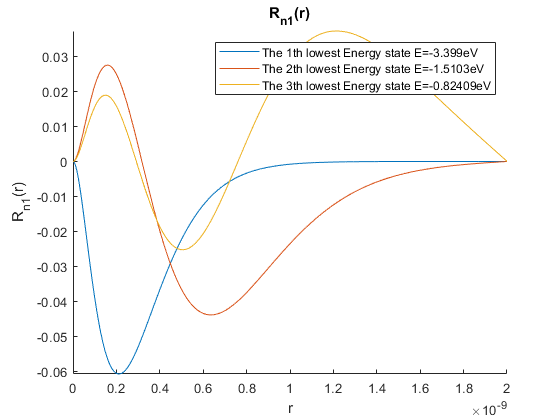

%Charge of the electron
q_e = 1.602e-19;
%Weight of the electron
m_e = 9.109e-31;
%Planc constant
h = 1.054572e-34;
%The value of h^2/2m
h_ = -h^2/(2.0*m_e);
%Vacuum permittivity
eps0 = 8.854187e-12;
%Length of the observed region
TotalLength = 2e-9;
%Resolution of the observed region
N = 2000;
k_e=1/(4*pi*eps0);
l=1;

WallWidth=10;
Wallenergy = 200*q_e;

%Place the coordinate system

r = linspace(0, TotalLength, N);
dr=TotalLength/N;

V=zeros(1, N);
angular=zeros(1, N);

V=(q_e^2 /(4*pi*eps0))*1./(abs(r));
    
angular=-h_.*((l*(l+1))./(abs(r)).^2);

u=angular-V;
    
H = zeros(N,N);
  for i = 2 : N-1
      H(i,i) = (-2.0*h_/dr^2)+u(i);
      H(i,i-1) = h_/dr^2;
      H(i,i+1) = h_/dr^2;
  end
    

%The sides of the matrix:
%Left side:
H(1,1) = (-2*h_/dr^2)+u(i);
H(1,2) = h_/dr^2;

%Right side:
H(N,N) = (-2*h_/dr^2)+u(i);
H(N,N-1) =h_/dr^2;

[Psi,Emx] = eig(H);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);

for i = 1:N
    E(i) = Emx(i,i);
end

%Finds the first n minimum-energy eigenvalue
n = 3;
E_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:,1) = Psi(:,MinEindex);
E_minValue(1) = MinE;

for i=2:n
    E(MinEindex) = E(MinEindex)+Wallenergy;
    [MinE,MinEindex] = min(E);
    Psi_n(:,i) = Psi(:,MinEindex);
    E_minValue(i) = MinE;
end

figure(4);
title('R_{n1}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat('The',32,num2str(i),'th lowest Energy state E=',num2str(E_minValue(i)/q_e),'eV'));
end
legend
xlabel('r');
ylabel('R_{n1}(r)')
axis tight;
hold off;

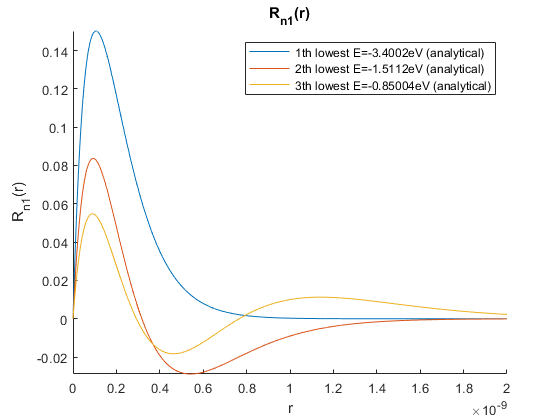


%analytic sol:

a = 5.29e-11;
E10 = -(m_e /(2*h^2)*(k_e*q_e^2)^2);
a_=a^(-3/2);
ar=r./a;

%Rnl; n=2,3,4; l=1
R21= 1/sqrt(24)*a_.*ar.*exp(-r./(2*a));
R31= 8/(27*sqrt(6))*a_.*(1-1/6.*ar).*ar.*exp(-r./(3*a));
R41= sqrt(5)/(16*sqrt(3))*a_.*(1-0.25.*ar+1/80.*ar.^2).*ar.*exp(-r./(4*a));


figure(5);
title('R_{n1}(r)');
hold on;
plot(r, a^(3/2).*R21, 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10*(1/4)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R31, 'DisplayName', strcat(32,num2str(2),'th lowest E=',num2str(E10*(1/9)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R41, 'DisplayName', strcat(32,num2str(3),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{n1}(r)')
axis tight;
hold off;

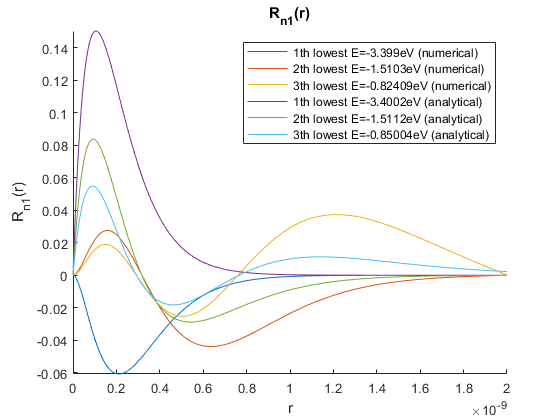


figure(6);
title('R_{n1}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV', ' (numerical)'));
end
plot(r, a^(3/2).*R21, 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10*(1/4)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R31, 'DisplayName', strcat(32,num2str(2),'th lowest E=',num2str(E10*(1/9)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R41, 'DisplayName', strcat(32,num2str(3),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{n1}(r)')
axis tight;
hold off;

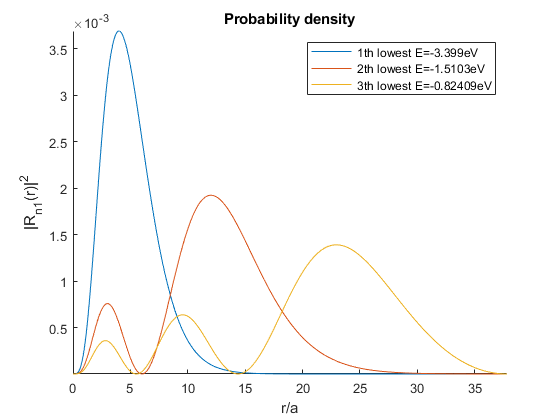


figure(34);
title('Probability density');
for i=1:n
    hold on;
    plot(r./a, abs(Psi_n(:,i)).^2, 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV'));
    xlabel('r/a')
    ylabel('|R_{n1}(r)|^2')
end
legend
axis tight;
hold off;

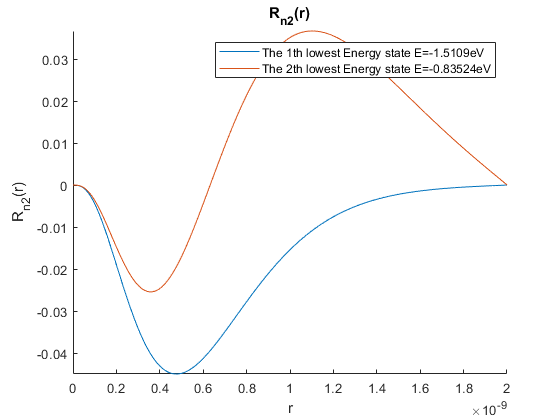

l=2;


V=zeros(1, N);
angular=zeros(1, N);

V=(q_e^2 /(4*pi*eps0))*1./(abs(r));
    
angular=-h_.*((l*(l+1))./(abs(r)).^2);

u=angular-V;
    
H = zeros(N,N);
  for i = 2 : N-1
      H(i,i) = (-2.0*h_/dr^2)+u(i);
      H(i,i-1) = h_/dr^2;
      H(i,i+1) = h_/dr^2;
  end
    

%The sides of the matrix:
%Left side:
H(1,1) = (-2*h_/dr^2)+u(i);
H(1,2) = h_/dr^2;
%Right side:
H(N,N) = (-2*h_/dr^2)+u(i);
H(N,N-1) =h_/dr^2;

[Psi,Emx] = eig(H);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);

for i = 1:N
    E(i) = Emx(i,i);
end

%Finds the first n minimum-energy eigenvalue
n = 2;
E_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:,1) = Psi(:,MinEindex);
E_minValue(1) = MinE;

for i=2:n
    E(MinEindex) = E(MinEindex)+Wallenergy;
    [MinE,MinEindex] = min(E);
    Psi_n(:,i) = Psi(:,MinEindex);
    E_minValue(i) = MinE;
end

figure(7);
title('R_{n2}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat('The',32,num2str(i),'th lowest Energy state E=',num2str(E_minValue(i)/q_e),'eV'));
end
legend
xlabel('r');
ylabel('R_{n2}(r)')
axis tight;
hold off;

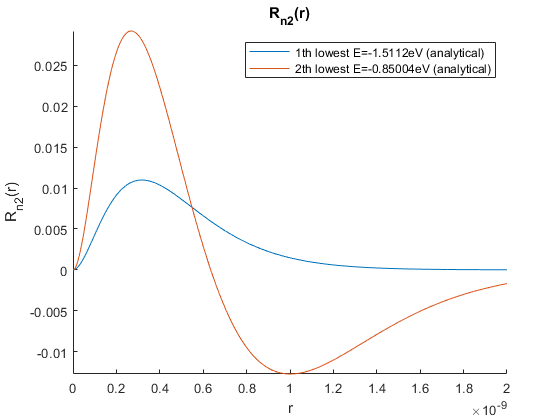


%analytic sol:

a = 5.29e-11;
E10 = -(m_e /(2*h^2)*(k_e*q_e^2)^2);
a_=a^(-3/2);
ar=r./a;

%Rnl; n=3,4; l=2
R32= 1/(81*sqrt(30))*a_.*ar.^2.*exp(-r./(3*a));
R42= 1 /(64*sqrt(5))*a_.*(1-1/12.*ar).*ar.^2.*exp(-r./(4*a));


figure(8);
title('R_{n2}(r)');
hold on;
plot(r, a^(3/2).*R32, 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10*(1/9)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R42, 'DisplayName', strcat(32,num2str(2),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{n2}(r)')
axis tight;
hold off;

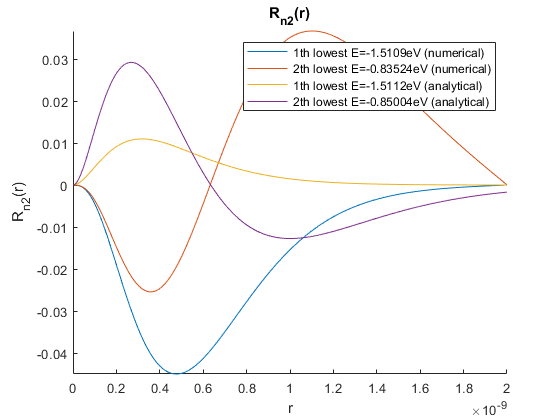


figure(9);
title('R_{n2}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV', ' (numerical)'));
end
plot(r, a^(3/2).*R32, 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10*(1/9)/q_e),'eV', ' (analytical)'));
plot(r, a^(3/2).*R42, 'DisplayName', strcat(32,num2str(2),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{n2}(r)')
axis tight;
hold off;

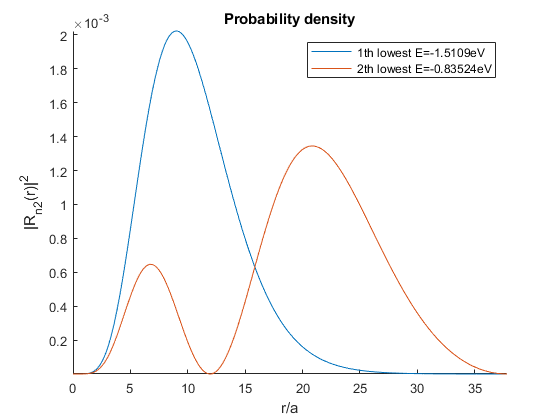


figure(35);
title('Probability density');
for i=1:n
    hold on;
    plot(r./a, abs(Psi_n(:,i)).^2, 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV'));
    xlabel('r/a')
    ylabel('|R_{n2}(r)|^2')
end
legend
axis tight;
hold off;

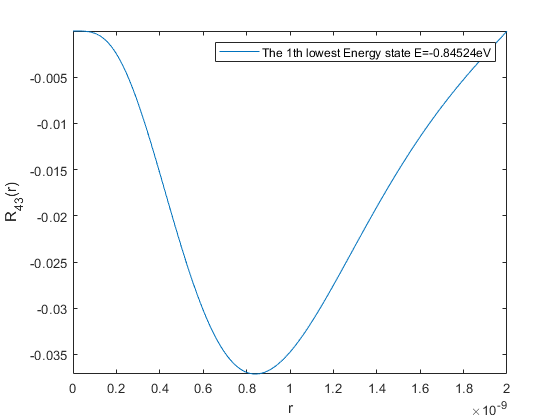

l=3;


V=zeros(1, N);
angular=zeros(1, N);

V=(q_e^2 /(4*pi*eps0))*1./(abs(r));
    
angular=-h_.*((l*(l+1))./(abs(r)).^2);

u=angular-V;
    
H = zeros(N,N);
  for i = 2 : N-1
      H(i,i) = (-2.0*h_/dr^2)+u(i);
      H(i,i-1) = h_/dr^2;
      H(i,i+1) = h_/dr^2;
  end
    

%The sides of the matrix:
%Left side:
H(1,1) = (-2*h_/dr^2)+u(i);
H(1,2) = h_/dr^2;

%Right side:
H(N,N) = (-2*h_/dr^2)+u(i);
H(N,N-1) =h_/dr^2;

[Psi,Emx] = eig(H);

%Makes a one-dimensional list from the energy matrix
E = zeros(1, N);

for i = 1:N
    E(i) = Emx(i,i);
end

%Finds the first n minimum-energy eigenvalue
n = 1;
E_minValue = zeros(n);

%Finds the minimum-energy eigenvalue
[MinE,MinEindex] = min(E);
MinE;
Psi_n(:,1) = Psi(:,MinEindex);
E_minValue(1) = MinE;

figure(10);
title('R_{43}(r)');
plot(r, Psi_n(:,1), 'DisplayName', strcat('The',32,num2str(1),'th lowest Energy state E=',num2str(E_minValue(1)/q_e),'eV'));
legend
xlabel('r');
ylabel('R_{43}(r)')
axis tight;
hold off;

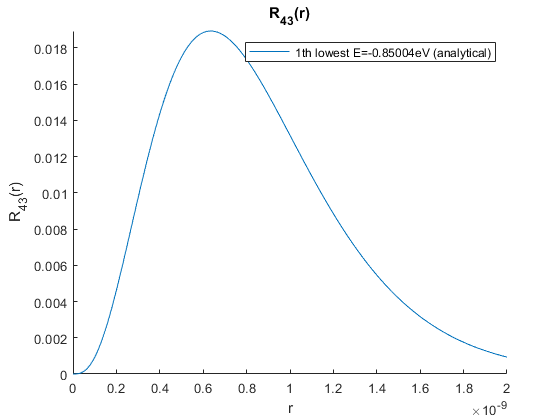


%analytic sol:

a = 5.29e-11;
E10 = -(m_e /(2*h^2)*(k_e*q_e^2)^2);
a_=a^(-3/2);
ar=r./a;

%Rnl; n=4; l=3
R43= 1/(768*sqrt(35))*a_.*ar.^3.*exp(-r./(4*a));


figure(11);
title('R_{43}(r)');
hold on;
plot(r, a^(3/2).*R43, 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{43}(r)')
axis tight;
hold off;

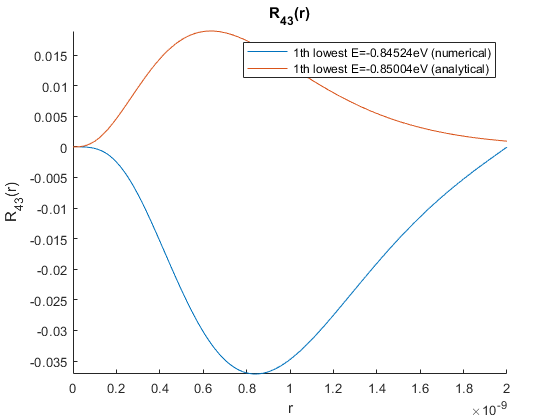


figure(12);
title('R_{43}(r)');
for i=1:n
    hold on;
    plot(r, Psi_n(:,i), 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV', ' (numerical)'));
end
plot(r, a^(3/2).*R43, 'DisplayName', strcat(32,num2str(1),'th lowest E=',num2str(E10*(1/16)/q_e),'eV', ' (analytical)'));
legend
xlabel('r');
ylabel('R_{43}(r)')
axis tight;
hold off;

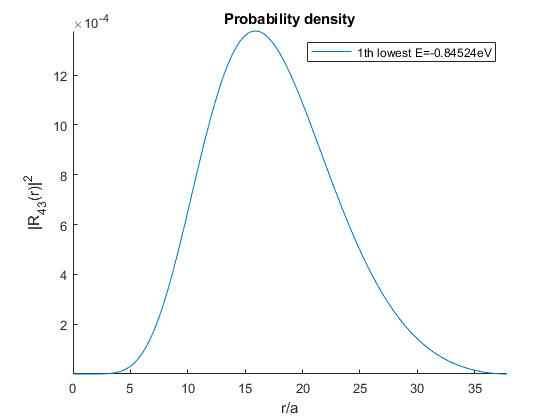


figure(36);
title('Probability density');
for i=1:n
    hold on;
    plot(r./a, abs(Psi_n(:,i)).^2, 'DisplayName', strcat(32,num2str(i),'th lowest E=',num2str(E_minValue(i)/q_e),'eV'));
    xlabel('r/a')
    ylabel('|R_{43}(r)|^2')
end
legend
axis tight;
hold off;

**Készítette: Bánkövi Orsolya, DAZOJ8**